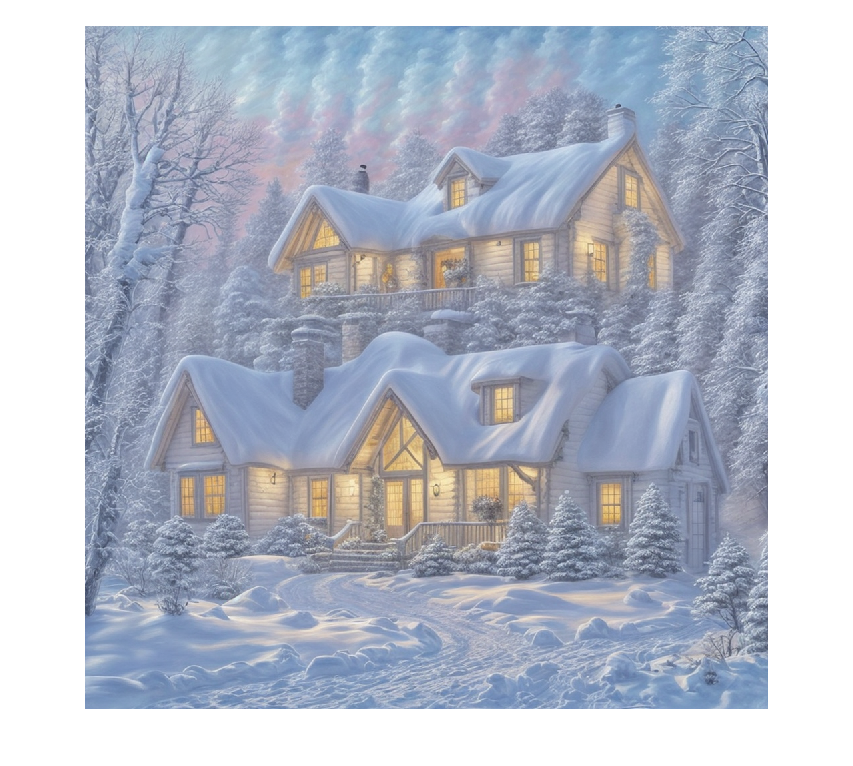

image = imread('task_1.png');

image = double(image);
image = image / 255;

imshow(image);

image_fourier = fftshift(fft2(image));

image_fourier_abs = abs(image_fourier);
image_fourier_arg = angle(image_fourier);

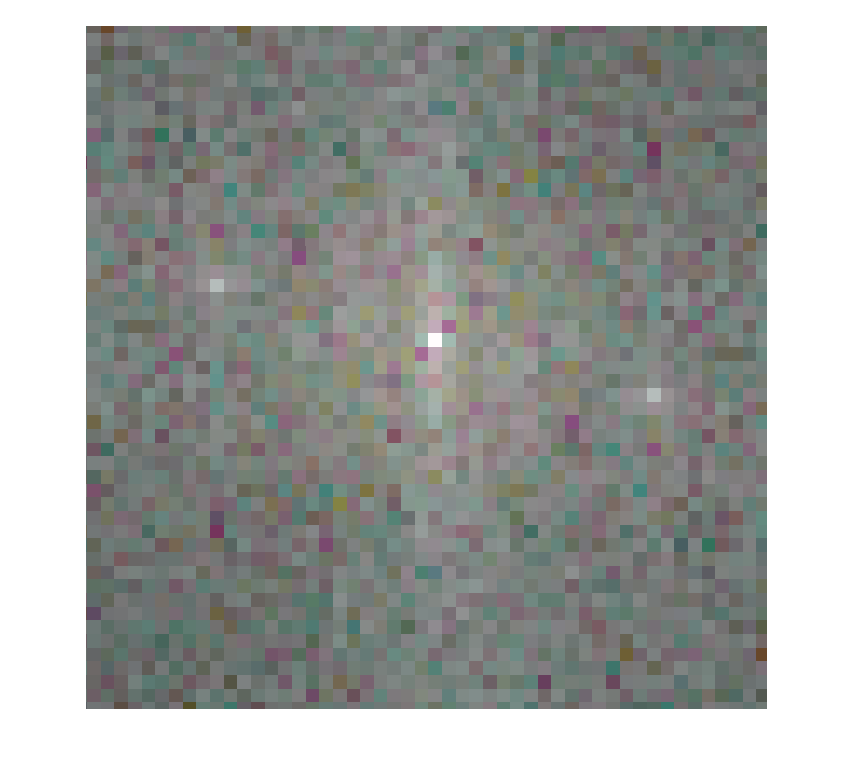

imshow(log_and_normalize(image_fourier_abs));
xlim([487.4 537.3]);
ylim([490.0 540.0]);

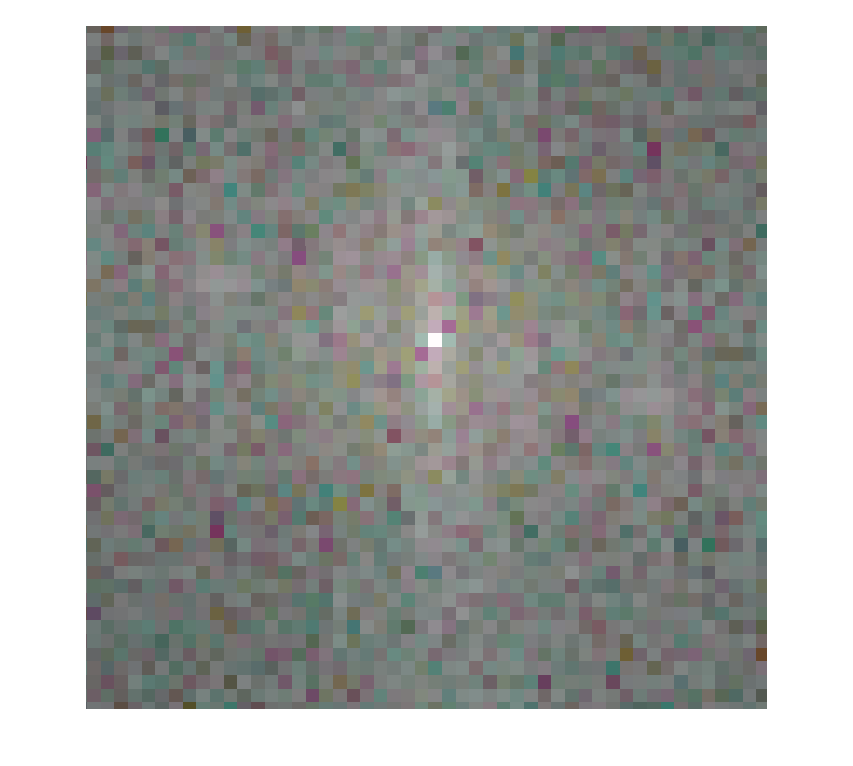

image_fourier_filtered = image_fourier_abs;
image_fourier_filtered(509, 497, :) = image_fourier_filtered(509, 497, :) / 7;
image_fourier_filtered(517, 529, :) = image_fourier_filtered(517, 529, :) / 7;

imshow(log_and_normalize(image_fourier_filtered));
xlim([487.4 537.3]);
ylim([490.0 540.0]);

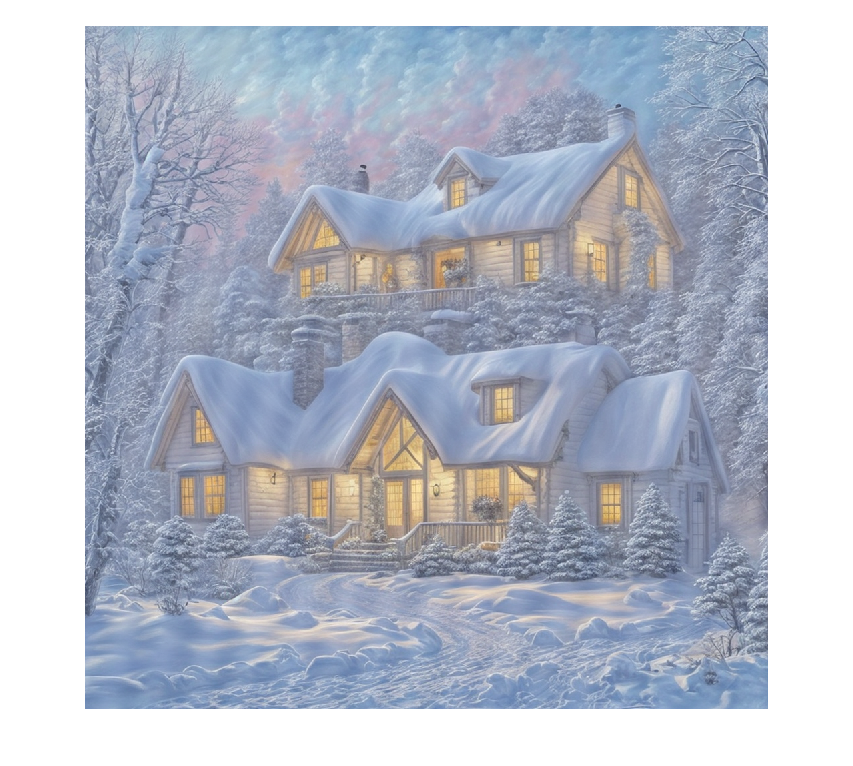

image_fourier_filtered = image_fourier_filtered .* exp(1i * image_fourier_arg);
image_filtered = ifft2(fftshift(image_fourier_filtered));

image_filtered = real(image_filtered) * 255;
image_filtered = uint8(image_filtered);

final_image = image_filtered;
final_image(:, :, 1) = image_filtered(:, :, 3);
final_image(:, :, 2) = image_filtered(:, :, 1);
final_image(:, :, 3) = image_filtered(:, :, 2);

imshow(final_image);

function arr = log_and_normalize(arr)
    arr = log(arr + 1);
    arr = arr / max(arr, [], "all");
end